# Sessió 9

Yimin Pan, Santi Otín

## Teoria 1

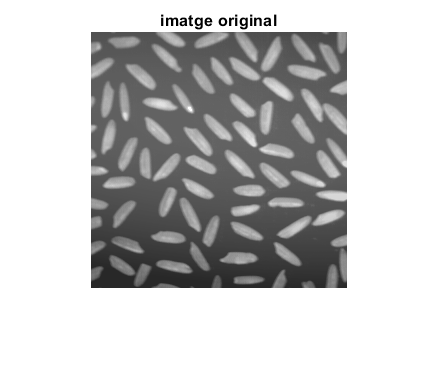

clear,close all
orig = imread('arros.tif');
figure, imshow(orig), title('imatge original')

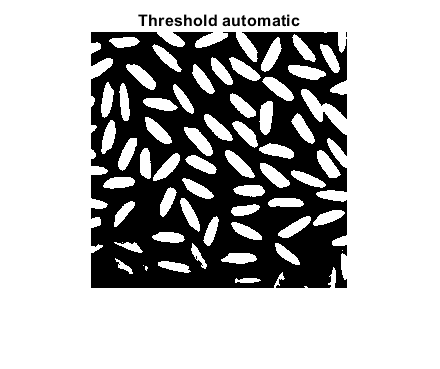

% segmentem per binarització
bw=im2bw(orig, graythresh(orig)); % Binarització per Otsu
figure, imshow(bw), title('Threshold automatic');

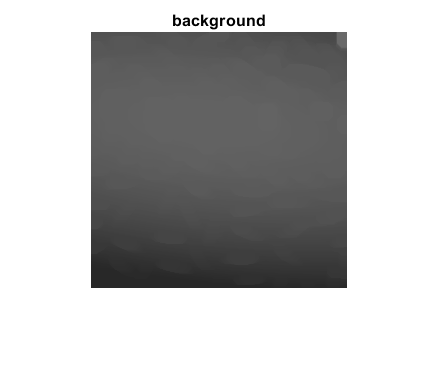

%No funciona, perdem grans. No confieu mai en els detectors automatics de llindar.
%El problema està en que la iluminació no és gens homogènea

% Fem un filtratge morfològic
bg = imopen(orig,strel('disk',10));
figure, imshow(bg), title('background');

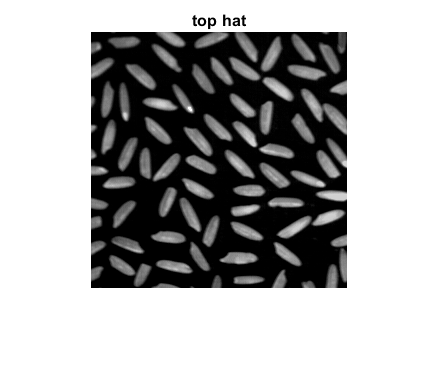

figure, surf(bg), title('bg superficie'); % mostrem el background com si fos una superfície

%Li restem el background a la imatge
y = imsubtract(orig,bg);
figure, imshow(y, []), title( 'top hat');

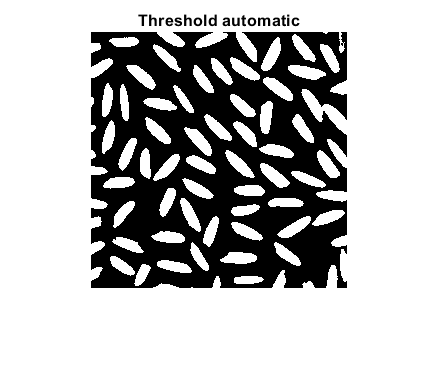


% tornem a segmentar per Otsu
bw=im2bw(y, graythresh(y));
figure, imshow(bw),title('Threshold automatic');

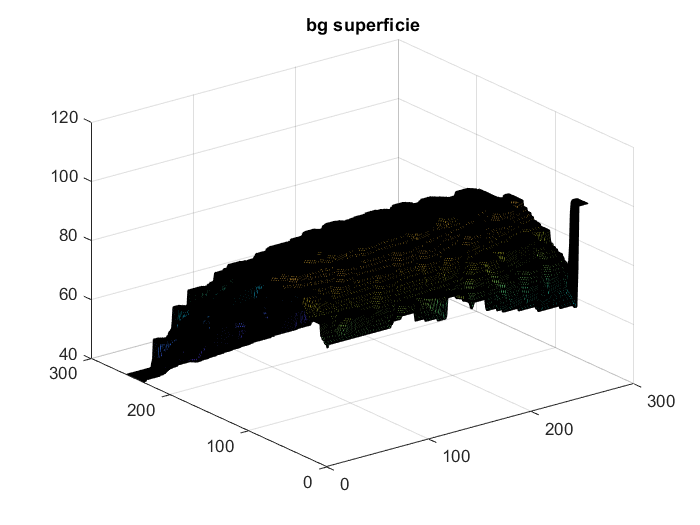

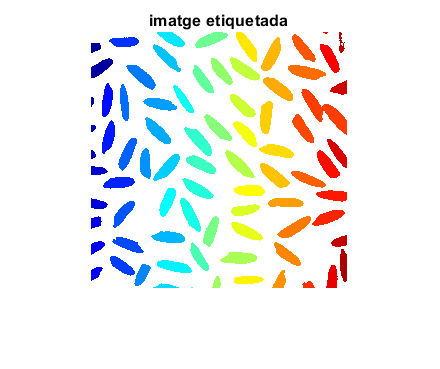

% Ara si!

% etiquetem la imatge segmentada
[eti num] = bwlabel(bw,4);
figure, imshow(label2rgb(eti)), title('imatge etiquetada');

% Comptem ara el nombre d’objectes a la imatge
num;
%o be:
max(eti(:));

% obtenim descriptors de les regions
Dades=regionprops(eti,'all');
%Comproveu en el workspace la variable Dades. Quines propietats hem extret de cada regió?
%Consulteu el help de la funció regionprops.

 % Podem obtenir una dada de l’objecte 50 de la forma:
Dades(50).Area;
% O be un vector amb totes les Àrees:
Arees=[Dades.Area];

## Exercici 1

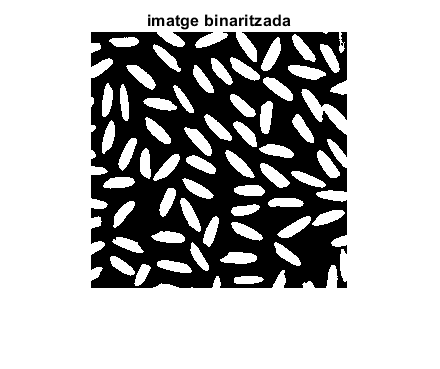

% Exercici: en la imatge segmentada, separeu els grans d'arròs que es toquen. Desprès elimineu els
% grans d'arròs que toquen les vores. Tots aquests grans falsejaven el resultat.
% Amb la nova imatge etiquetatda, obteniu les propietats que us semblin adients usant regionprops.
% Representeu mitjançant plots o diagrames de barres aquelles propietats que us semblin interessants
% per a fer un control de qualitat dels grans d'arròs.

figure, imshow(bw); title('imatge binaritzada');

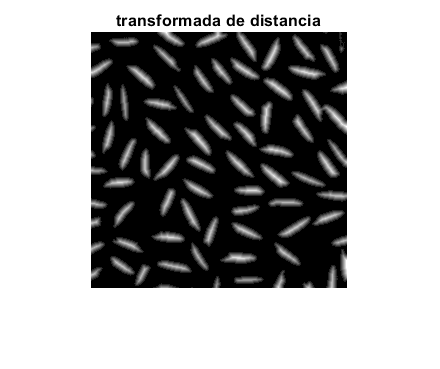

D = bwdist(~bw);
figure, imshow(D,[]), title('transformada de distancia');

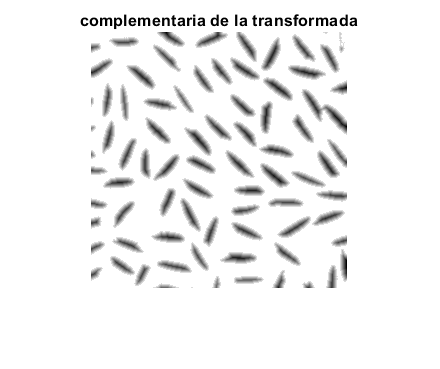

D = -D;
figure, imshow(D,[]);title('complementaria de la transformada');

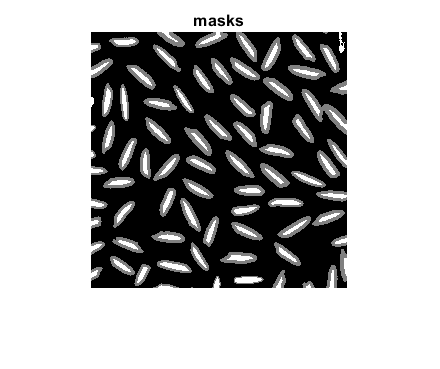


%para que no haya una superdivisión, usamos imextendedmin para juntar los
%minimos locales. Hemos usado este link como fuente para evitar esta superdivisión
% https://blogs.mathworks.com/steve/2013/11/19/watershed-transform-question-from-tech-support/
mask = imextendedmin(D,2);
figure, imshowpair(bw,mask,'blend'), title('masks');

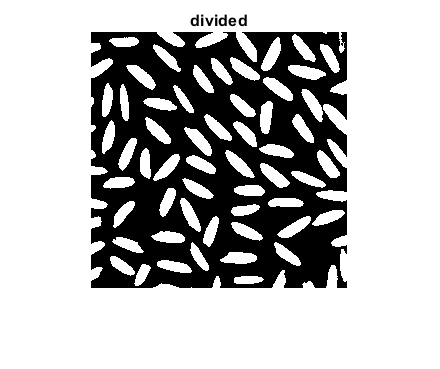

D2 = imimposemin(D,mask);
L = watershed(D2);
bw(L == 0) = 0;
figure, imshow(bw), title('divided');

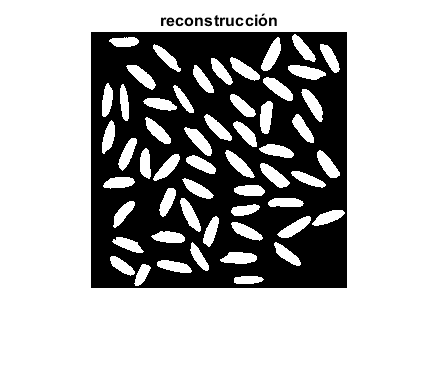


%%reconstrucción
mark=true(256); 
mark(2:end-1,2:end-1)=0; 
rec=imreconstruct(mark, bw); 
res = imsubtract(bw,rec);
figure, imshow(res),title('reconstrucción');

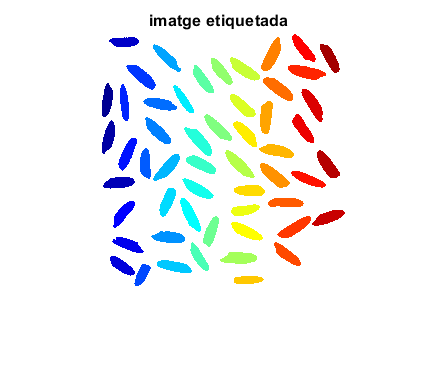


% etiquetem la nova imatge
[eti num] = bwlabel(res,4);
figure, imshow(label2rgb(eti)), title('imatge etiquetada');

num

num = 54

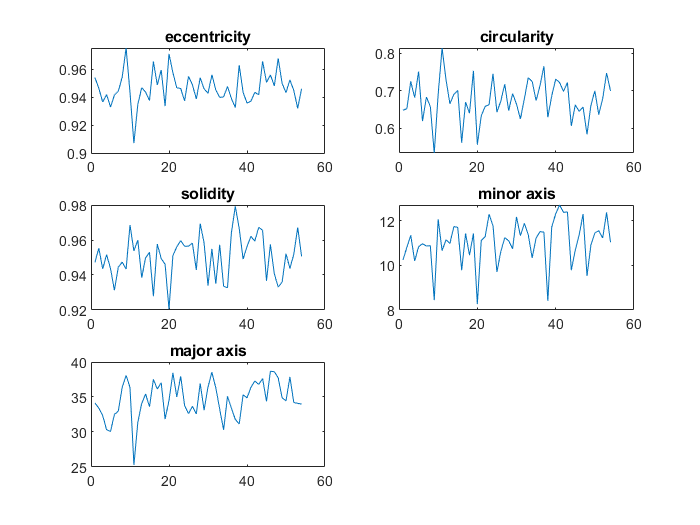


% obtenim descriptors de les regions
Dades=regionprops(eti,'all');
x = [1:1:num];

%les propietats que creiem que son mes interesants son la circularity,
%solidity y eccentricity. Aquestes propietats podem observar que excepte en
%alguns casos, no varien gaire
%els eixos de tots els grans d'arros també son semblants, encara que son
%variants al tamany del gra
figure;
subplot(3,2,1),plot(x, [Dades.Eccentricity]), title('eccentricity');
subplot(3,2,2),plot(x, [Dades.Circularity]), title('circularity');
subplot(3,2,3),plot(x, [Dades.Solidity]), title('solidity');
subplot(3,2,4),plot(x, [Dades.MinorAxisLength]), title('minor axis');
subplot(3,2,5),plot(x, [Dades.MajorAxisLength]), title('major axis');

## Teoria 2. Codis de Cadena

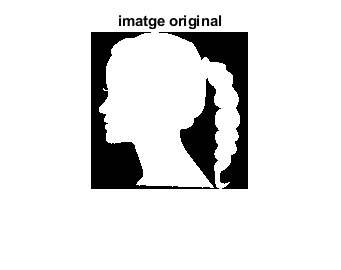

% 2. Codis de cadena
%clear all, close all
im=imread('head.png');
% no cal tan gran
im=imresize(im,1/4);
figure; imshow(im), title('imatge original');

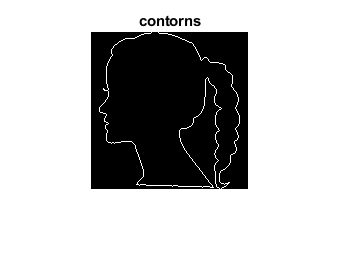

% obtenim el contorn
ero=imerode(im,strel('disk',1));
cont=xor(ero,im);
figure; imshow(cont), title('contorns');

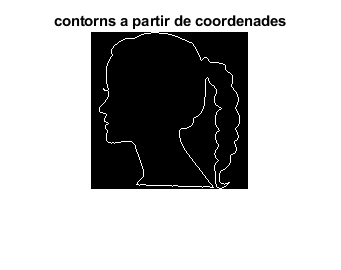

% obtenim les coordenades del contorn
[fila col] = find(im,1); % Busquem el primer píxel
B = bwtraceboundary(im,[fila col],'E'); %direccio est a l'atzar
% B conté les coordenades
% Ho comprovem mostrant el resultat
aux=zeros(size(im));
aux(sub2ind(size(aux),B(:,1),B(:,2)))=1;
figure; imshow(aux),title ('contorns a partir de coordenades');

## Exercici 2

% Exercici: trobar els codis de cadena incrementals a partir de B

% calculem la diferencia entre punts
d = diff(B);

% aquesta expressió ens retorna valors únics per a les 7 
% coordenades diferents possibles 
%               3  2  1
%                \ | /
%             4 -- P -- 0
%                / | \
%               5  6  7
%           -----------------------------------
%           | row_diff | col_diff | direction |
%           |---------------------------------|
%           |    +1    |     0    |     6     |
%           |    +1    |    +1    |     7     |
%           |     0    |    +1    |     0     |
%           |    -1    |    +1    |     1     |
%           |    -1    |     0    |     2     |
%           |    -1    |    -1    |     3     |
%           |     0    |    -1    |     4     |
%           |    +1    |    -1    |     5     |
%           -----------------------------------
dMap = 4*d(:,1) + d(:,2) + 7;
index([2 3 4 6 8 10 11 12]) = [3 2 1 4 0 5 6 7];

% codi de cadena
cc = index(dMap);
% codi de cadena incremental
cci = mod(diff([cc(end), cc])+8,8);

## 3. Descriptors de Fourier

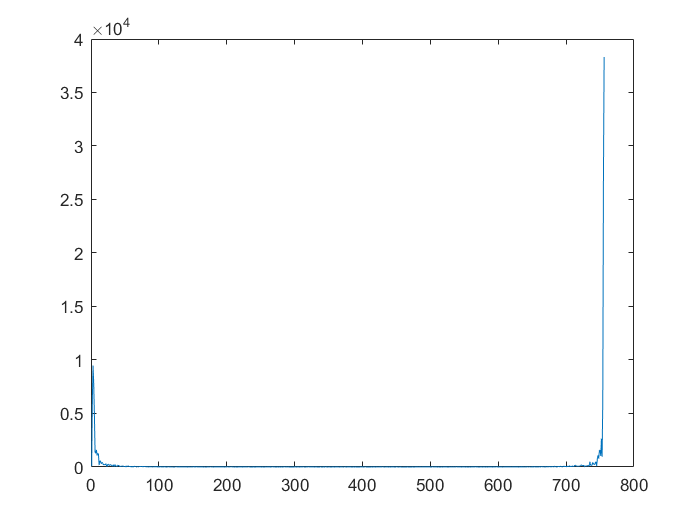

% centrem coordenades
mig=mean(B);
B(:,1)=B(:,1)-mig(1);
B(:,2)=B(:,2)-mig(2);
% Convertim les coordenades a complexes
s= B(:,1) + i*B(:,2);
% Cal que la dimensio del vector sigui parell
[mida bobo]=size(B);
if(mida/2~=round(mida/2))
s(end+1,:)=s(end,:); %dupliquem l'ultim
mida=mida+1;
end
% Calculem la Fast Fourier Transform
z=fft(s);
% representem l’espectre
figure,plot(abs(z))

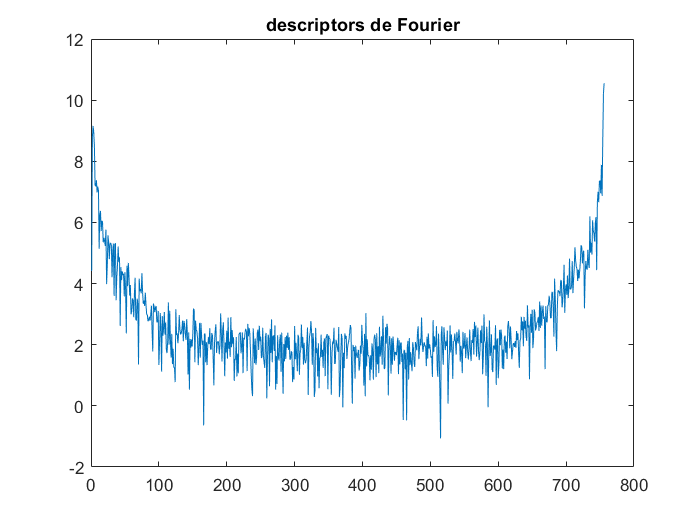

% ho displaiem logaritmic perque no es veu res
figure,plot(log(abs(z))), title ('descriptors de Fourier')

Observeu que l’espectre surt duplicat, amb un efecte mirall. És una propietat de la trasnformada de Fourier, que ara no ve al cas. 

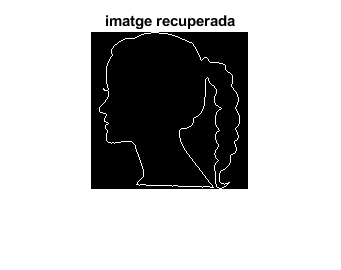

% Recuperem la imatge original per comprovar que el procés és reversible
ss=ifft(z); % Transformada de Fourier inversa
files= round(real(ss)+mig(1));
cols=round(imag(ss)+mig(2));
aux(:,:)=0;
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux), title('imatge recuperada')

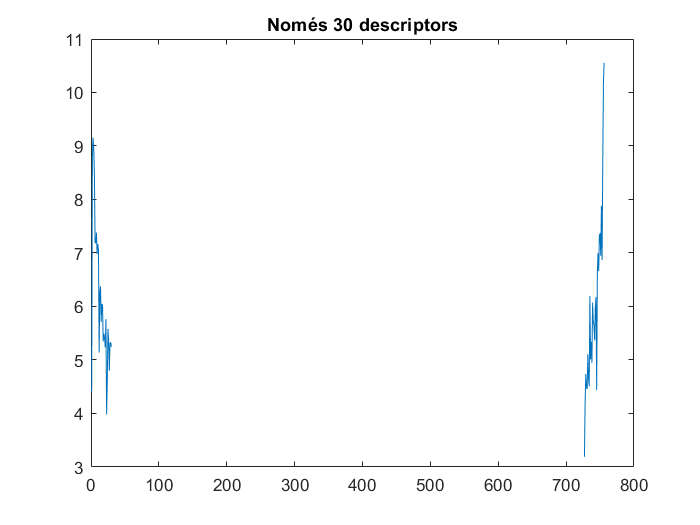


%% Reduim la quantitat de descriptors de Fourier
N=30; % agafem N descriptors
tmp=z;
tmp(N+1:end-N)=0; % eliminem els del mig perque es duplica l'espectre
figure, plot(log(abs(tmp))), title ('Només 30 descriptors')

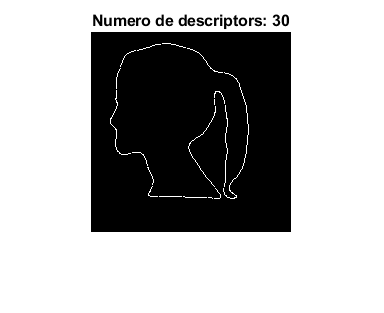


% Tornem al pla imatge a partir de l’espectre modificat
ss2=ifft(tmp);
% Les coordenades resultants poden sortir del rang de la imatge original
% Creo una imatge més gran per a que les coordenades no s'em surtin de marge
mida=200;
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux2=logical(zeros(mida));
aux2(sub2ind(size(aux2),files,cols))=1;
figure,imshow(aux2)
title(['Numero de descriptors: ',num2str(N)]);

exercici: Repetiu el procés utilitzant diferents quantitats de descriptors i expliqueu quin efecte té això en el detall de la imatge obtinguda

#### 10 descriptors

N=10; 
tmp=z;
tmp(N+1:end-N)=0; 
ss2=ifft(tmp);
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux3=logical(zeros(mida));
aux3(sub2ind(size(aux3),files,cols))=1;

#### 100 descriptors

N=100; 
tmp=z;
tmp(N+1:end-N)=0; 
ss2=ifft(tmp);
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux4=logical(zeros(mida));
aux4(sub2ind(size(aux4),files,cols))=1;

#### 378 (756/2) descriptors

N=378; 
tmp=z;
tmp(N+1:end-N)=0; 
ss2=ifft(tmp);
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux5=logical(zeros(mida));
aux5(sub2ind(size(aux5),files,cols))=1;

#### 600 descriptors

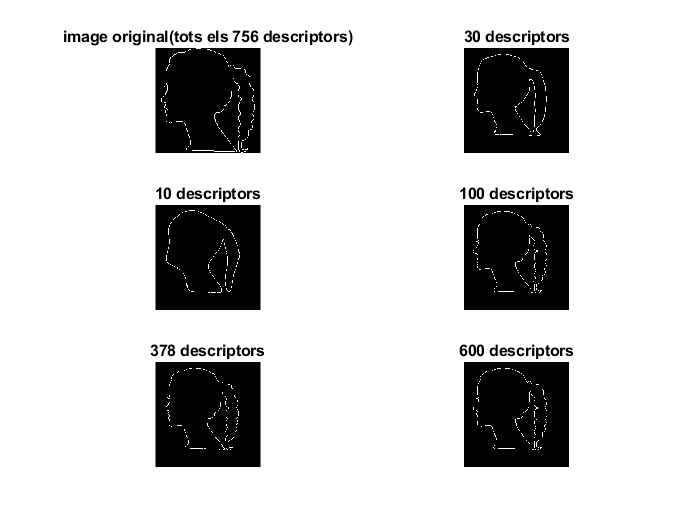

N=600; 
tmp=z;
tmp(N+1:end-N)=0; 
ss2=ifft(tmp);
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux6=logical(zeros(mida));
aux6(sub2ind(size(aux6),files,cols))=1;

figure; subplot(3,2,1); imshow(aux); title('image original(tots els 756 descriptors)');
subplot(3,2,2); imshow(aux2); title('30 descriptors');
subplot(3,2,3); imshow(aux3); title('10 descriptors');
subplot(3,2,4); imshow(aux4); title('100 descriptors');
subplot(3,2,5); imshow(aux5); title('378 descriptors');
subplot(3,2,6); imshow(aux6); title('600 descriptors');

Per la teoría sabem que podem representar funcions periódiques com combinacions de funcions sinuisoidals amb frequencies diferents (descriptors de Fourier).

Llavors, quan usem pocs descriptors (components de més baixa freqüencia) obtenim una descripció molt aproximada de la forma del objecte, i a mesura que aumentem el nombre de descriptors estem afegint els termes de Fourier amb freqüencia més alta, i aixó afegeix detall a l'imatge resultant. 

L'imatge original té 756 descriptors, peró no ens oblidem que l'espectre està duplicat, lo qual fa que amb la meitat del nombre de descriptors (378) ja és suficient per obtenir una imatge tan detallat com l'original.